ns = 4:100;
ms = 4:100;

load('timing_get_c_from_d_H_mlx.mat');

results = {};

while 1
    n = datasample(ns, 1);
    m = datasample(ms, 1);
    fprintf("%d %d\n", n, m);
    results{end + 1} = get_timing_results(n, m);
    save('timing_get_c_from_d_H_mlx');
end

13 31
22 74
97 69
91 11
16 14
84 53
93 48
41 16
59 91
76 55
14 59
13 65
94 46
87 40
25 16
86 72
70 35
20 4
71 43
25 51
59 98
27 67
53 11
12 51
8 73
34 56
53 35
57 81
92 29
36 13
75 58
25 83
61 67
23 77
85 73
4 15
22 30
83 31
75 24
10 12
96 50
78 24
56 60
15 58
21 19
11 42
44 8
23 79
10 71
19 89
88 15
14 61
65 94
94 9
23 42
100 14
32 36
59 44
40 82
8 34
87 27
33 8
34 98
29 55
94 33
69 87
47 84
83 62
94 11
22 73
29 6
88 35
98 90
22 100
52 83
67 99
46 73
14 10
25 23
74 24
25 7
61 42
4 73
22 37
99 71
47 77
52 23
81 79
84 51
38 32
49 63
86 85
6 79
82 12
66 70
69 55
64 60
79 46
72 35
31 45
66 95
67 71
28 41
60 77
92 23
83 15
89 11
86 60
13 16
98 86
19 93
66 97
61 72
41 47
51 75
12 44
46 85
92 55
96 43
66 99
78 99
16 86
92 56
80 81
73 23
38 16
47 57
64 65
59 47
63 90
36 47
28 69
95 94
61 42
5 55
20 6
23 7
38 22
49 69
48 27
66 92
96 53
43 90
49 84
98 57
94 37
11 26
73 79
67 94
65 11
60 60
23 42
52 70
75 86
7 86
75 98
37 20
26 8
72 48
84 90
37 83
49 42
36 25
86 65
76 73
43 11
95 82
57 76
59 97


plot_ns = [];
plot_ms = [];
plot_c_plus_time = [];
plot_c_minus_time = [];
for i=1:size(results, 2)
    r = results{i};
    plot_ns(end + 1) = r('n');
    plot_ms(end + 1) = r('m');
    plot_c_plus_time(end + 1) = r('c_plus_time');
    plot_c_minus_time(end + 1) = r('c_from_d_time');
end
save('timing_get_c_from_d_H_mlx_arr', 'plot_ns', 'plot_ms', 'plot_c_minus_time', 'plot_c_plus_time')

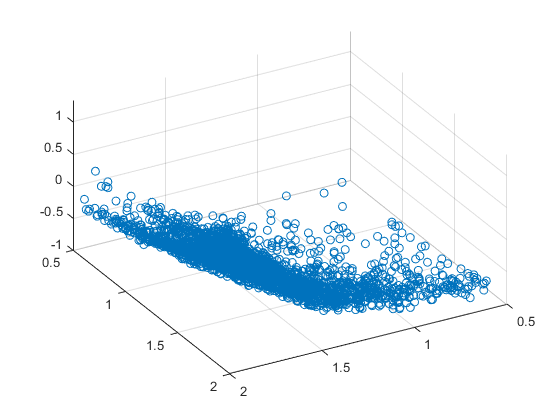

scatter3(log10(plot_ns), log10(plot_ms), log10(plot_c_minus_time))

save()

function results = get_timing_results(n, m)
results = containers.Map;
results('n') = n; results('m') = m;
[A, b] = get_random_f(n, m);
%results('A') = A; results('b') = b;

tic;
c_plus = get_c_plus(A);
results('c_plus_time') = toc;

z_max_guess = 1e-5;
results('z_max_guess') = z_max_guess;

y = point_inside(A, b, c_plus, z_max_guess);
results('y') = y;

% H from article
% Using original map to avoid precision loss caused by change_basis()
H = get_H(A, b);

d = randn(m, 1);
results('d') = d;


% obtaining c via dual problem from d
tic;
c = get_c_from_d_H(H, y, d);
results('c_from_d_time') = toc;
results('c') = c;
end